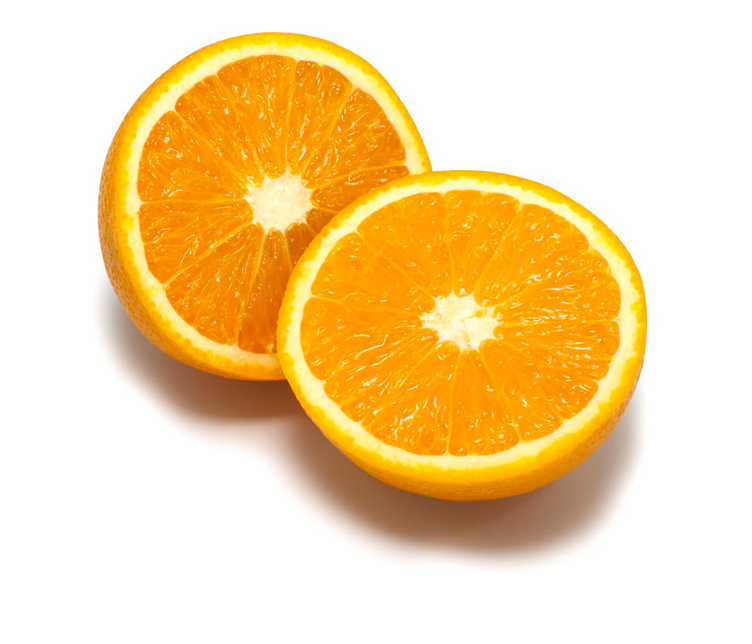

K = 8;               % number of clusters used
L = 6;              % number of iterations
seed = 20;           % seed used for random initialization
scale_factor = 1.0;  % image downscale factor
image_sigma = 1.0;   % image preblurring scale

I = imread('orange.jpg');
imshow(I);

I = imresize(I, scale_factor);
Iback = I;
d = 2*ceil(image_sigma*2) + 1;
h = fspecial('gaussian', [d d], image_sigma);
I = imfilter(I, h);

% [ segm, centers ] = kmeans_segm(I, K, L, seed);
% disp(centers);
% Inew = mean_segments(Iback, segm);
% I = overlay_bounds(Iback, segm);
% imshow(Inew);
% imshow(I);

% Q2
prev_centers = [];
for K = 2:10
    converged = false;
    for L = 1:50
        [ segm, centers ] = kmeans_segm(I, K, L, 'default');
        
        if L > 1
            largest_diff = max(abs(centers - prev_centers),[],'all');
            if largest_diff < 0.5
                converged = true;
                break
            end
        end
        prev_centers = centers;
    end
    if converged == true
        disp(sprintf("K = %i converged at L = %i", K, L));
    end
end

K = 2 converged at L = 2
K = 3 converged at L = 4
K = 4 converged at L = 4
K = 5 converged at L = 8
K = 6 converged at L = 8


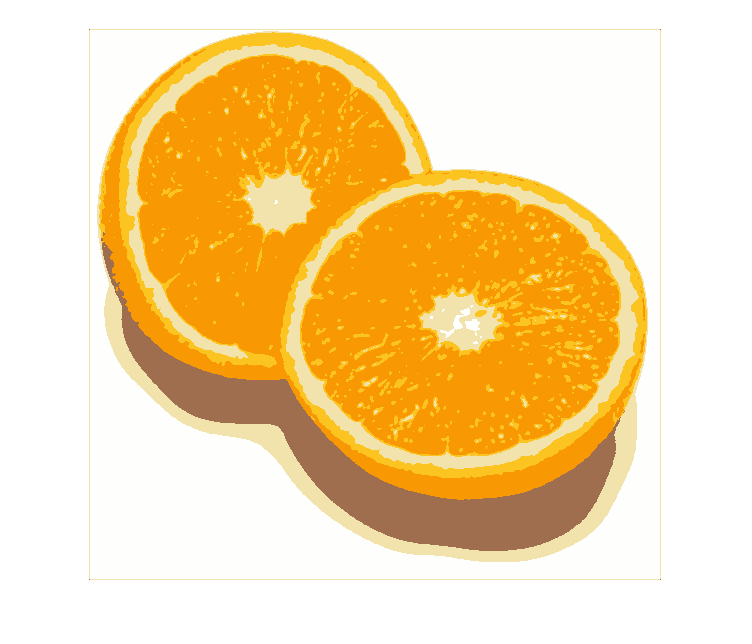

% Q3
K = 10;
L = 20;
[ segm, centers ] = kmeans_segm(I, K, L);
Inew = mean_segments(Iback, segm);
Ibounds = overlay_bounds(Iback, segm);
imshow(Inew);

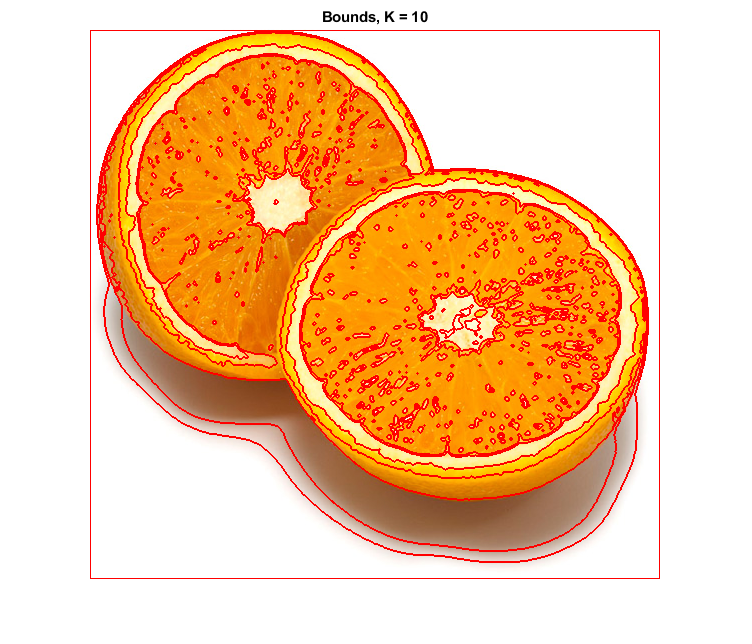

imshow(Ibounds);
title(sprintf("Bounds, K = %i", K));